# The Collins synthetic genetic switch

JH, 2/23/21 

Gardner, T.S., Cantor, C.R., and Collins, J.J. (2000). Construction of a genetic toggle switch in Escherichia coli. Nature 403, 339?342. 

Solves:


$${\frac{du}{dt}}={\frac{a1}{1+b_1v^4}}-u$$
      
$${\frac{dv}{dt}}={\frac{a1}{1+b_1u^4}}-v$$


Decrease b1 to weaken inhibition by v and u goes high

Decrease a1 to switch to v high 

Decrease a2 to switch to u high 

## Parameter values

param.n1=4;
param.n2=4;
param.a1=2;
param.a2=2;
param.b1=1;         %symmetric
%param.b1=.1;       %"u-on" state
param.b2=1;

## First plot the nullclines

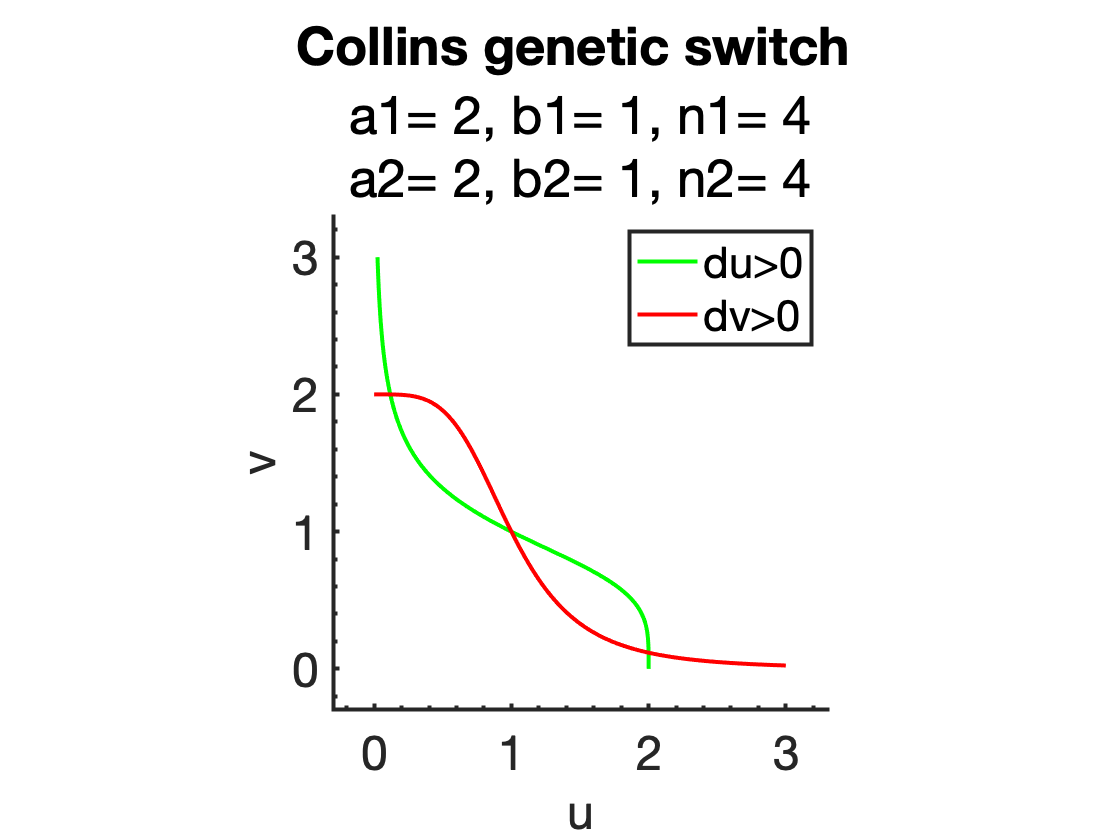

xx=[0:.01:3];

close all; figure; hold on;

plot(param.a1./(1+param.b1*xx.^param.n1),xx,'g');
plot(xx,param.a2./(1+param.b2*xx.^param.n2),'r');
axis square;
xlabel('u');
ylabel('v');
legend('du>0','dv>0','Location','Northeast');%legend BOXON;
title({['Collins genetic switch ' ]});
subtitle({[ ...
    'a1= ' num2str(param.a1) ...
    ', b1= ' num2str(param.b1) ...
    ', n1= ' num2str(param.n1)];[ ...
    'a2= ' num2str(param.a2) ...
    ', b2= ' num2str(param.b2) ...
    ', n2= ' num2str(param.n2)]});
%set(gca,'OuterPosition',[0.05 0.05 .95 .95]);
%set(gcf,'position',[100,100,450,450]);
PrettyFig;

## Shade regions

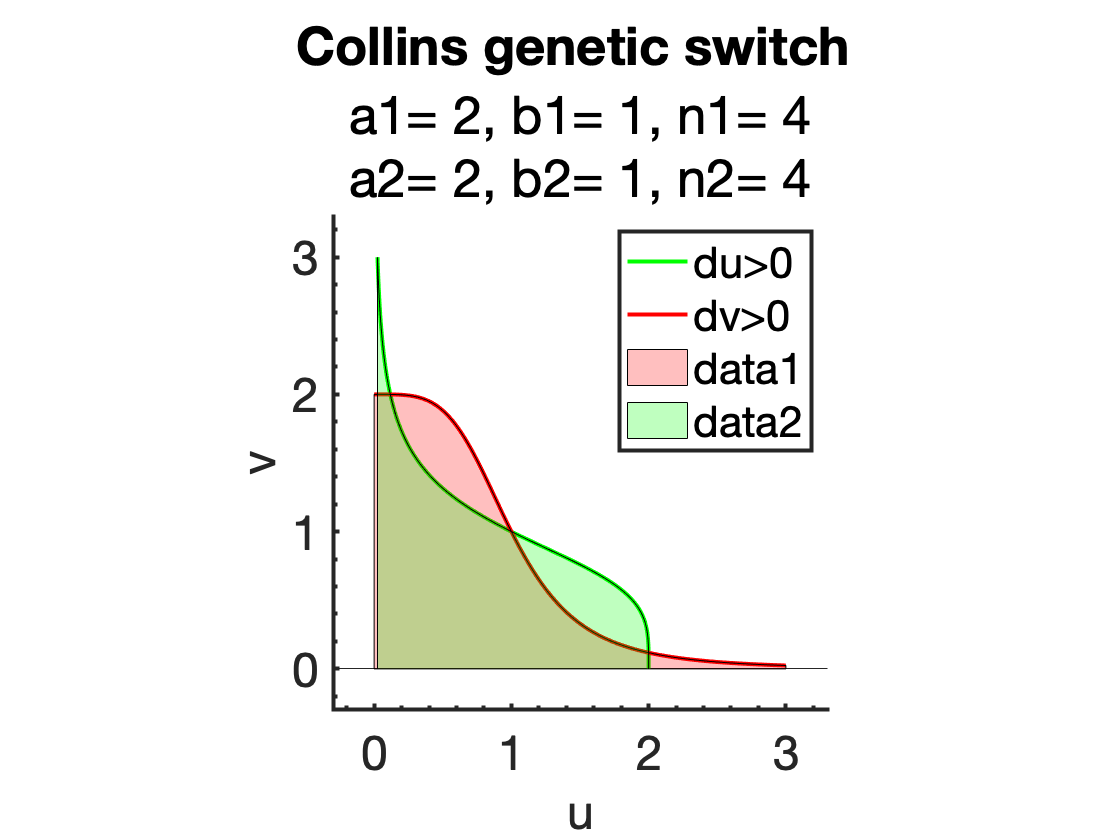

h1=area(xx,param.a2./(1+param.b2*xx.^param.n2));
set( h1, 'FaceColor', 'r')
%alpha(.25);
h2=area(param.a1./(1+param.b1*xx.^param.n1),xx);
set( h2, 'FaceColor', 'g')
alpha(.25);

## Add the vector field

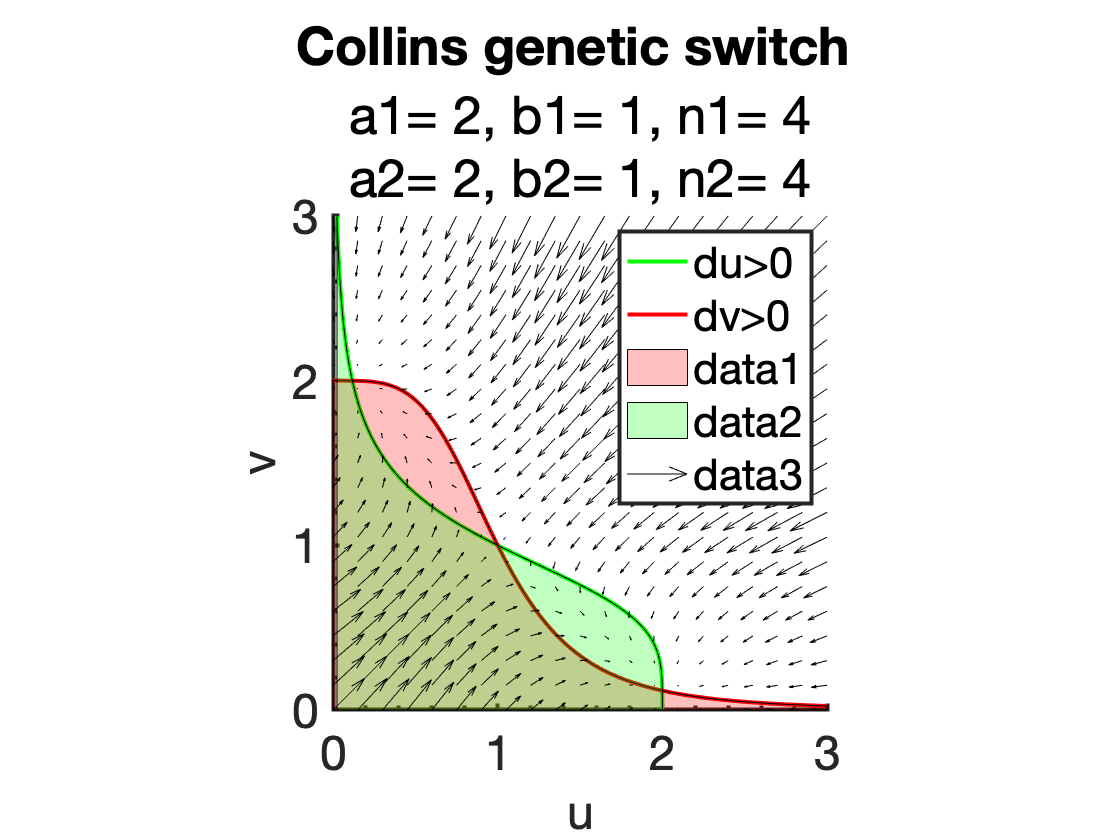

[y1,y2]=meshgrid([0:.15:3],[0:.15:3]);
dy1dt = param.a1./(1+param.b1*y2.^param.n1)-y1;
dy2dt = param.a2./(1+param.b2*y1.^param.n2)-y2;
quiver(y1,y2,dy1dt,dy2dt,2,'color','k');

axis([0 3 0 3]);